# Test on training of logistic regression model

In this example, we compare "swarmCBO" to the PSO implementation "particleswarm" of the MATLAB global optimization toolbox. We consider a high-dimensional problem consisiting on learning the parameter of a logistic regression model

We start by creating a synthetic data set for binary classification:

clear all

dim =100; %problem dimension
k = 1000; %number of data points 
Z = randn(k, dim);
theta_star = rand(dim,1);  %base model parameter
nu = randn(k, 1)*1e-6;  %noise

% creation of the labels for 0-1 cla
T = 1./(1 + exp(-(Z*theta_star + nu)))';
T(T>0.5) = 1;
T(T<=0.5) = 0;

Different options of loss can be selected. Definition are 

function [out] = obj_Accuracy(theta,Z,T)
% accuracy
H = 1./(1 + exp(-theta*Z'));
H(H>0.5) = 1;
H(H<=0.5) = 0;
out =  mean(T==H,2);
end

function [out] = obj_CrossEntropy(theta,Z,T)
% cross entropy loss (modified to avoid NaN outputs)
H = 1./(1 + exp(-theta*Z'));
H(H==0) = 1e-8;
H(H==1) = 1- 1e-8;
entropy  = - T.*log(H) -(1-T).*log(1-H);
out = mean(entropy,2);
end

function [l2] = obj_L2loss(theta,Z,T)
%L2 loss function
H = 1./(1 + exp(-theta*Z'));
l2 = mean((T - H).^2,2);
end

%fun = @(x) obj_CrossEntropy(x, Z, T);
%fun = @(x) obj_L2loss(x, Z, T);
fun = @(x) - obj_Accuracy(x, Z, T);

rng default  % For reproducibility

Next, we select the options for the algorithms. This can modified to set different paramters.

optionsCBO = optimoptions('particleswarm','SwarmSize',1000,'Display','off', ...
    'MinNeighborsFraction',1,'InertiaRange',[0,0],'UseVectorized',true);
param.cLambda1 = 0;
param.cSigma1 = 0;

optionsPSO = optimoptions('particleswarm','SwarmSize',1000,'Display','off',...
    'MinNeighborsFraction',1,'UseVectorized',true);

nvars = dim;
lb = -10*ones(1,nvars);
ub = 10*ones(1,nvars);


We now perform the experiments and collect data for statistics.

numtests = 5

numtests = 5

entropyCBO = zeros(numtests,1);
accuracyCBO = zeros(numtests,1);
entropyPSO = zeros(numtests,1);
accuracyPSO = zeros(numtests,1);

for nt  = 1:numtests
    [x,fval,exitflag,output,points]= swarmCBO(fun,nvars,lb,ub,optionsCBO,param);
    entropyCBO(nt) = obj_CrossEntropy(x,Z, T);
    accuracyCBO(nt) = obj_Accuracy(x,Z, T);
    x = particleswarm(fun,nvars,lb,ub,optionsPSO);
    entropyPSO(nt) = obj_CrossEntropy(x,Z, T);
    accuracyPSO(nt) = obj_Accuracy(x,Z, T);
end

Now, we visualize the median values obtained.

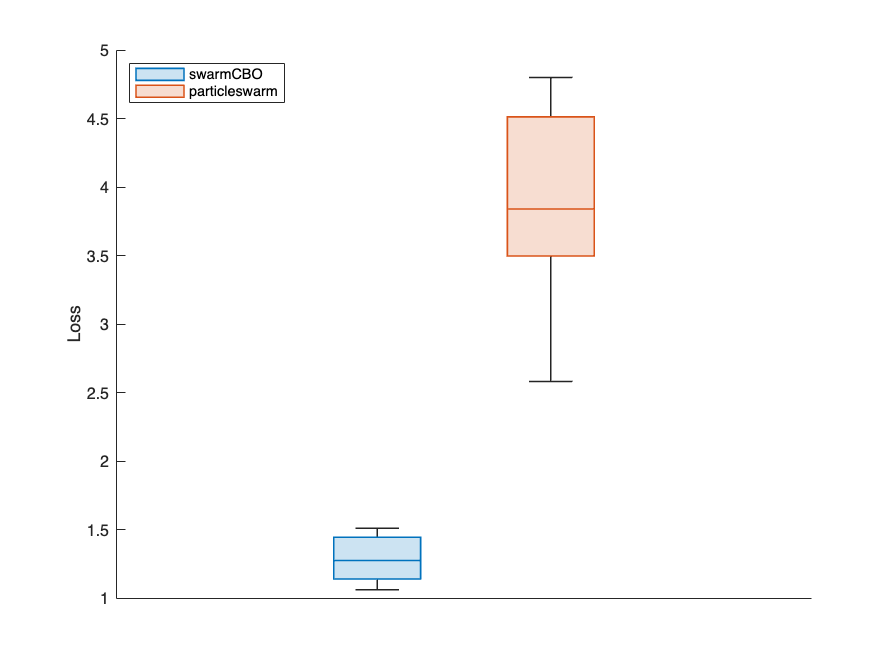

cat = [zeros(numtests,1); ones(numtests,1)];
cat = categorical(cat,[0 1],{'swarmCBO' 'particleswarm'});
data_ce  = [entropyCBO;entropyPSO];
tbl = table(data_ce,cat);

figure;
boxchart(tbl.data_ce,'GroupByColor',tbl.cat,Orientation = 'vertical')
ylabel('Loss')
xticks('')
legend('Location','northwest')

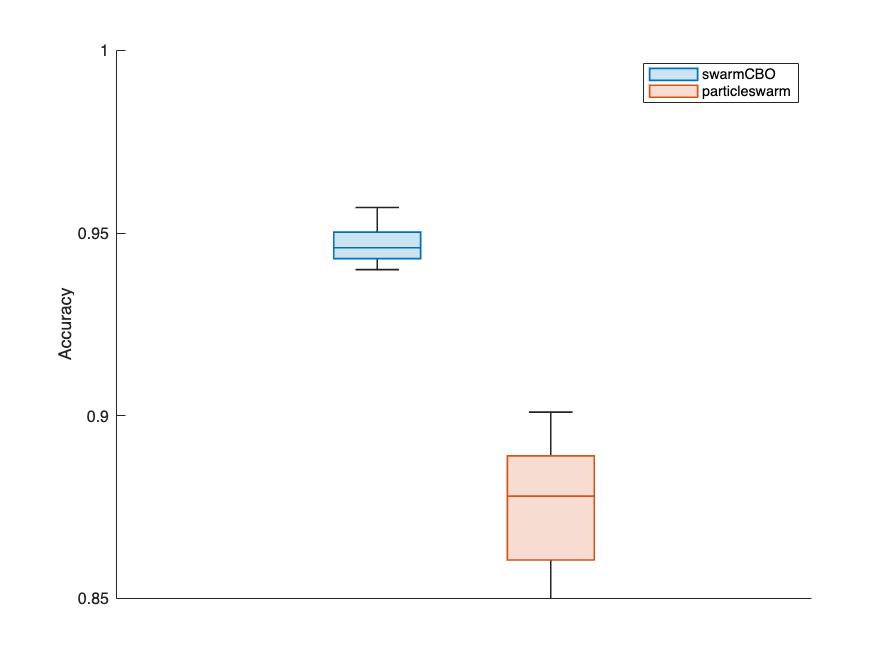


figure;
cat = [zeros(numtests,1); ones(numtests,1)];
cat = categorical(cat,[0 1],{'swarmCBO' 'particleswarm'});
data_ce  = [accuracyCBO;accuracyPSO];
tbl = table(data_ce,cat);

boxchart(tbl.data_ce,'GroupByColor',tbl.cat,Orientation = 'vertical')
ylabel('Accuracy')
ylim([0.85,1])
xticks('')
legend